% เคลียร์ข้อมูลก่อนรันโค้ดใหม่
clear all, close all, clc

% โหลดข้อมูลจาก m-file "raw_data_table.mat"
load("raw_data_table.mat")

% ชื่อคอลัมน์ทั้งหมดจากตาราง "raw_data_table"
column_names = raw_data_table.Properties.VariableNames;
% เปลี่ยนชุดข้อมูลในรูปแบบ table ให้อยู่ในรูปแบบ array
raw_data = table2array(raw_data_table); % size 2879x26

% จัดการ Outliers
clean_data = rmoutliers(raw_data,"mean"); % size 2706x26

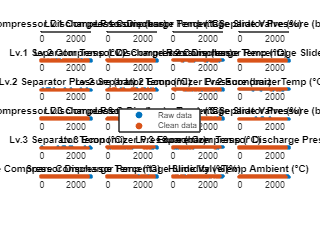

% Create subplots for each column
figure('Name','Raw data and Cleaned data');
% figure;
for i = 1:size(clean_data, 2)-2
    subplot(6, 4, i);
    scatter(1:size(raw_data,1), raw_data(:,i), 10, 'filled');
    hold on;
    scatter(1:size(clean_data,1), clean_data(:,i), 10, 'filled');
    title(column_names{i});
%      legend('Raw', 'Cleaned');

end
% Create a common legend outside the subplot
legend({'Raw data','Clean data'}, 'Location','none');

% สร้างตารางข้อมูล
claen_table = array2table(clean_data);

% กำหนดชื่อคอลัมน์
claen_table.Properties.VariableNames = column_names;

% บันทึกตารางเป็นไฟล์ Excel
writetable(claen_table, 'NEW_clean_data.xlsx');
